syms s t

A = [-1 -0.5; 1 0];
B = [0.5 ; 0];
C = [1 0];
D = 0;
t1 = [0:0.05:10];

sys = ss(A,B,C,D);
[num, den] = ss2tf(A,B,C,D);
tf(num, den)


ans =
 
      0.5 s
  -------------
  s^2 + s + 0.5
 
Continuous-time transfer function.


mf = inv(s*eye(1) - A)

$$mf = \left(\begin{array}{cc} \frac{2\,s}{3\,s+1} & -\frac{2\,s+1}{3\,s+1}\\ -\frac{2\,\left(s-1\right)}{3\,s+1} & \frac{2\,\left(s+1\right)}{3\,s+1} \end{array}\right)$$

mt = ilaplace(mf, t)

$$mt = \left(\begin{array}{cc} \frac{2\,\delta (t)}{3}-\frac{2\,{\mathrm{e}}^{-\frac{t}{3}}}{9} & -\frac{{\mathrm{e}}^{-\frac{t}{3}}}{9}-\frac{2\,\delta (t)}{3}\\ \frac{8\,{\mathrm{e}}^{-\frac{t}{3}}}{9}-\frac{2\,\delta (t)}{3} & \frac{4\,{\mathrm{e}}^{-\frac{t}{3}}}{9}+\frac{2\,\delta (t)}{3} \end{array}\right)$$

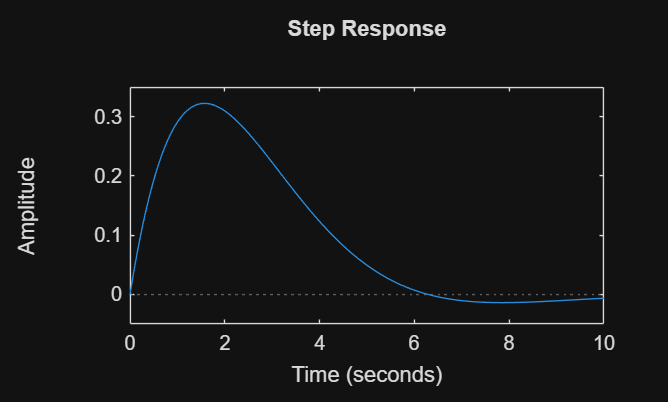


step(sys,t1);

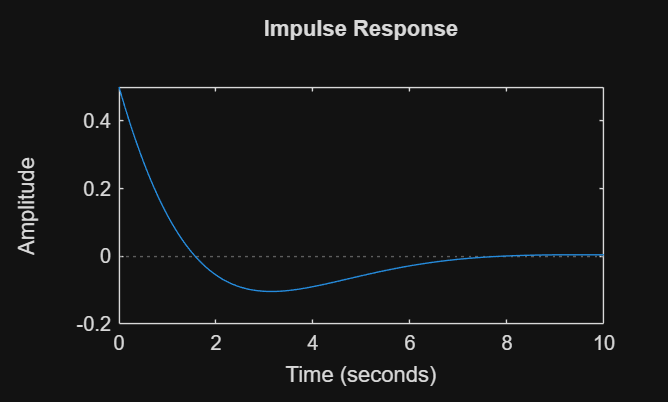

impulse(sys, t1);


ctb = det(ctrb(A,B))

ctb = 0.2500

obs = det(obsv(A,C))

obs = -0.5000